**EE-414 Speech Processing Lab**

**Lab-4**

**7/02/2021**

**Name:Vaishnavi Patil**

**Roll. No:180020039**

**AIM**

- To understand the time and frequency domain characteristics of **voiced and unvoiced speech**.

- To perform the voiced/unvoiced/silence classification of speech.

**THEORY**

From the understanding of signal and systems, the speech production system responds to the input excitation by producing speech signal.

                                                                   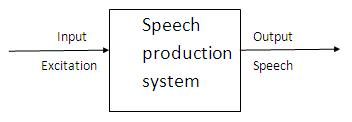

The speech production organs include lungs, trachea, glottis, pharynx, oral cavity and nasal cavity. The lungs supply the required air during exhalation for producing speech. Trachea also termed as wind pipe connects the lungs to the glottis. The glottis consists of two thin membranes termed as vocal folds or chords and obstruct airflow during specific category speech to generate the required excitation signal for speech production. The organs above glottis constitute the system part for speech production.

Based on the input excitation phenomenon, the speech production can be broadly categorized into three activities. 

1) **Voiced Speech **: Input excitation is nearly periodic in nature. 

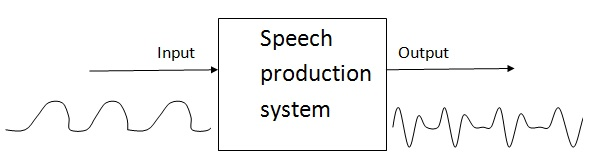

Production: During the production of voiced speech, the air exhaling out of lungs through the trachea is interrupted periodically by the vibrating vocal folds. Due to this, the glottal wave is generated that excites the speech production system resulting in the voiced speech.

Thus grossly, when we look at the speech signal waveform, **if it looks nearly periodic in nature, then it can be marked as voiced speech.**

**Autocorrelation Analysis **: The periodicity associated with the voiced speech can be **pitch period**. The distance of the first largest peak in the autocorrelation sequence from the beginning represents pitch period. This is the important and main distinguishing factor for voiced speech. 

**Sprectrum Analysis **: Since voiced speech is periodic in nature, we expect some fundamental frequency and its harmonics in the spectrum of speech.  In the frequency domain, the presence of this harmonic structure is the main distinguishing factor for voiced speech. The fundamental frequency of input excitation is also termed as **pitch frequency **or just **pitch **.

2) **Unvoiced Speech : **Input excitation is random noise-like in nature and the resulting speech will also be random noise-like without any periodic nature.

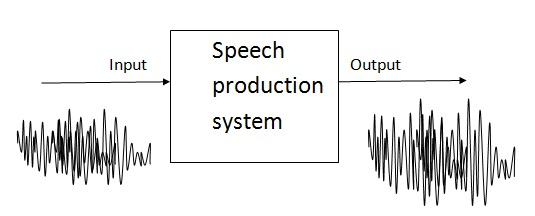

Production :During the production of unvoiced speech, the air exhaling out of lungs through the trachea is not interrupted by the vibrating vocal folds. However, starting from glottis, somewhere along the length of vocal tract, total or partial closure occurs which results in obstructing air flow completely or narrowly. This modification of airflow results in stop or frication excitation and excites the vocal tract system to produce unvoiced speech. 

Main distinguishing Factor: The unvoiced speech will not have any periodic nature. This will be the main distinction between voiced and unvoiced speech.

Autocorrelation analysis: In case of unvoiced, there will be no strong peak indicating periodicity.

Spectrum Analysis: In the frequency domain, the** absence of this harmonic structure** is the main distinguishing factor for unvoiced speech.

**3) Silence :** During silence region, there is no excitation supplied to the vocal tract and hence no speech output.

Production: The speech production process involves generating voiced and unvoiced speech in succession, separated by what is called **silence region**. Without the presence of silence region between voiced and unvoiced speech, the speech will not intelligible. Further, the duration of silence along with other voiced or unvoiced speech is also an indicator of certain category of sounds. If the signal amplitude is low or negligible, then it can be marked as silence.

The study of these regions is the aim of this experiment.

**PROCEDURE**

A ) Record the phrase “**Speech signal**” and plot the time waveform. Use 16kHz and 16 bits/sample as the sampling frequency and bit resolution respectively.

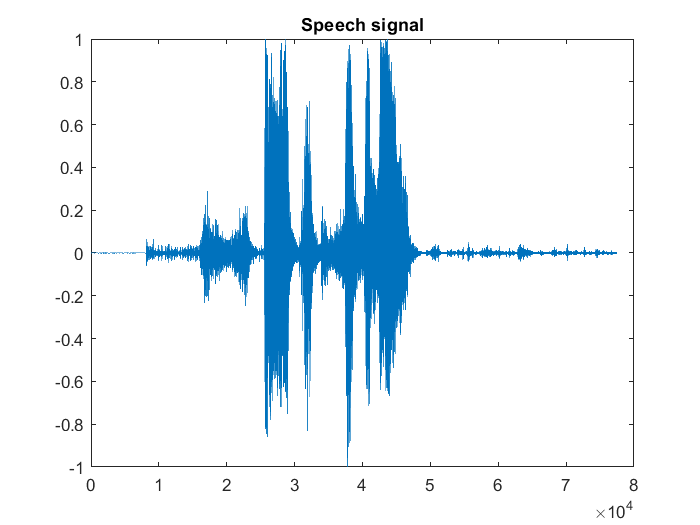

[y1,Fs] = audioread('speechsignal16k.wav'); %speech recorded at 16kHz
[y] = quan(y1,16);  %bit resolution 16 bits/sample
sound(y,Fs);
figure();
plot(y);                
title('Speech signal')

B ) Examine  "s", "ch",  any one vowel, any one nasal from A as follows. Take one segment of 25 ms duration at the centre of the sound. Compute and plot the Autocorrelation function, and comment on the periodicity of the sounds. Compare the autocorrelation plots for various sounds and comment on how autocorrelation can be used for classifying the sounds as voiced and unvoiced.

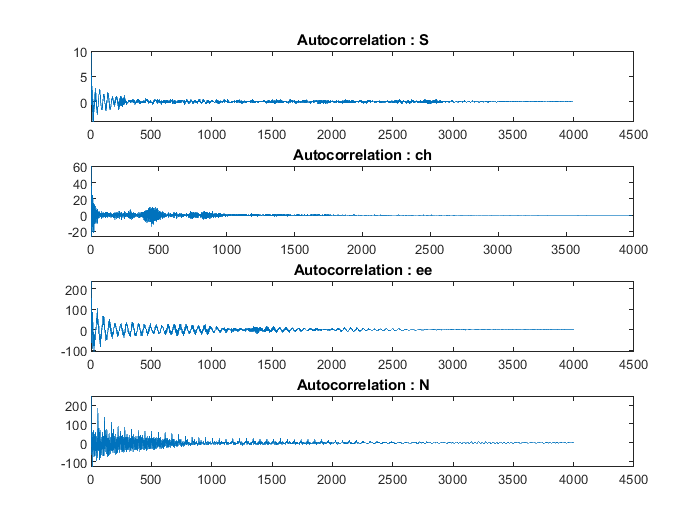

fs = 16000;
%----------------------------------------------Step 1 : Consider 25ms of each sound---------------------------------------------------%
%----------------------------Sound " S"----------------%
t1=2.085*fs : 2.335*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
%----------------------------Sound "ch"----------------%
t2=1.863*fs : 2.112*fs ; % Time Observed From Wavesurfer
t2=round(t2);
x2=y(t2);
%----------------------------Sound: Vowel "ee"----------------%
t3=1.657*fs : 1.907*fs ; % Time Observed From Wavesurfer
t3=round(t3);
x3=y(t3);
%----------------------------Sound : nasal"N"----------------%
t4=2.580*fs : 2.830*fs ; % Time Observed From Wavesurfer
t4=round(t4);
x4=y(t4);
%---------------------------------------- Step 2 : Autocorrelation--------------------------------------------------------------------%
[autocorr1] = autocr(x1);
[autocorr2] = autocr(x2);
[autocorr3] = autocr(x3);
[autocorr4] = autocr(x4);
figure();
subplot(4,1,1);
plot(autocorr1);
title('Autocorrelation : S');
subplot(4,1,2);
plot(autocorr2);
title('Autocorrelation : ch');
subplot(4,1,3);
plot(autocorr3);
title('Autocorrelation : ee');
subplot(4,1,4);
plot(autocorr4);
title('Autocorrelation : N');

**Comments and observations:**

**A strong peak indicating periodicity can be observed in autocorrelation of "ee" and "N". Further, the peak is at higher amplitude. Thus, "ee" and "N" are classified as Voiced sounds.**

**Whereas, no such peak is observed in "S" and "ch" and th autocorrelation appears very noisy and random. Thus, "S" and "ch" are classified as "unvoiced" sounds.**

C. Consider the 4 speech sounds mentioned in B and one silence segment.  For each of these 5 audio segments, compute and plot **Short Term Zero-Crossing** rate and the **Short Term Energy **as a function of frame index for all the frames in the sound. Use 25 msec and 10msec as frame_size and frame_shift respectively. Comment on how you would use these time-domain features for classifying the sounds as voiced or unvoiced or silence.

**Theory : **

**Short Term Energy :** The energy associated with speech is time varying in nature. Hence the interest for any automatic processing of speech is to know how the energy is varying with time and to be more specific, energy associated with short term region of speech. By the nature of production, the speech signal consist of voiced, unvoiced and silence regions. Further the energy associated with voiced region is large compared to unvoiced region and silence region will not have least or  negligible energy. Thus short term energy can be used for voiced, unvoiced and silence classification of speech.

**Zero Crossing Rate** gives information about the number of zero-crossings present in a given signal. Intuitively, if the number of zero crossings are more in a given signal, then the signal is changing rapidly and accordingly the signal may contain  high frequency information.  On the similar lines, if the number of zero crossing are less, hence the signal is changing slowly and accordingly the signal may contain low frequency information. Thus ZCR gives an indirect information about the frequency content of the signal. **ZCR is higher unvoiced sounds than voiced.**

[STE1] = short_term_energy(x1,16000,25,10)

STE1 =     0.1213    0.1318    1.4215    2.7011    2.6059    1.4917    1.3656    0.9678    0.5829    0.4197    0.4021    0.3897    0.3783    0.3077    0.3851    0.4688    0.7693    0.9075    0.7979    0.7893    0.8170    1.0841


[STE2] = short_term_energy(x2,16000,25,10)

STE2 =     0.2703    0.1811    0.1378    0.1009    0.1363    0.2594    0.5852    1.6557    3.4075   10.3849   19.6759   26.8527   24.6904   24.1283   19.9168   10.6524    5.3212    1.5258    0.6366    0.4808    0.4156


[STE3] = short_term_energy(x3,16000,25,10)

STE3 =    41.4978   30.1401   29.1965   28.8160   28.4452   28.2713   31.3731   36.3175   39.3409   35.2444   34.6506   42.7816   51.1300   49.5750   33.7189   16.3813    4.2174    1.7200    0.9169    0.5721    0.3469    0.2351


[STE4] = short_term_energy(x4,16000,25,10)

STE4 =     9.6188    8.7264    8.2806    5.4134    5.7278    7.7856   18.4241   31.3211   38.8117   35.0276   35.1413   38.3312   42.2945   49.6436   49.3333   45.9398   36.5995   28.0228   25.4750   23.2367   21.2595   17.5158


[ZCR1] = zero_crossing_rate(x1,16000,25,10)

ZCR1 =     0.2050    0.1713    0.1187    0.0775    0.0862    0.2013    0.3013    0.3075    0.2587    0.2500    0.2712    0.2800    0.3013    0.3063    0.3275    0.3563    0.3725    0.3850    0.3475    0.3275    0.3275    0.3425


[ZCR2] = zero_crossing_rate(x2,16000,25,10)

ZCR2 =     0.1462    0.1462    0.1462    0.1588    0.2025    0.2450    0.2850    0.3025    0.3113    0.3187    0.3088    0.3262    0.3362    0.3337    0.3375    0.3250    0.2938    0.2662    0.2525    0.2100    0.1837


[ZCR3] = zero_crossing_rate(x3,16000,25,10)

ZCR3 =     0.2125    0.2087    0.2000    0.2075    0.2162    0.2112    0.2062    0.1963    0.1900    0.1862    0.1713    0.1512    0.1363    0.1450    0.1138    0.1100    0.1363    0.1550    0.1350    0.1212    0.1388    0.1512


[ZCR4] = zero_crossing_rate(x4,16000,25,10)

ZCR4 =     0.0413    0.0425    0.0600    0.0800    0.0775    0.0612    0.0638    0.0925    0.1225    0.1263    0.1225    0.1138    0.1150    0.1163    0.1200    0.1263    0.1375    0.1512    0.1613    0.1575    0.1600    0.1363


%----------------------------Silence----------------%
t5=1.478*fs : 1.590*fs ; % Time Observed From Wavesurfer
t5=round(t5);
x5=y(t5);
[STE5] = short_term_energy(x5,16000,25,10)

STE5 =     0.0784    0.0660    0.0508    0.0466    0.0255    0.0230    0.0312    0.0437


[ZCR5] = zero_crossing_rate(x5,16000,25,10)

ZCR5 =     0.1263    0.0887    0.0825    0.0800    0.0775    0.0737    0.0762    0.0587


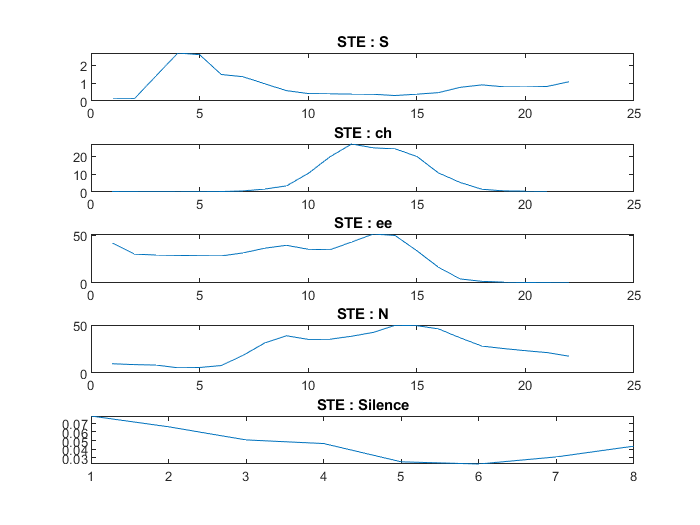


figure();
subplot(5,1,1);
plot(STE1);
title('STE : S');
subplot(5,1,2);
plot(STE2);
title('STE : ch');
subplot(5,1,3);
plot(STE3);
title('STE : ee');
subplot(5,1,4);
plot(STE4);
title('STE : N');
subplot(5,1,5);
plot(STE5);
title('STE : Silence');

**Comments and observations : **

**It can be observed that Short-term Energy is significantly higher in case of "ee", which is classified as voiced sound.**

**Next, the nasal sounds "n" have secong highest STE, which is also a bit of  voiced sound.**

** ch and s (fricative)  have lowest STE: all these are classified into unvoiced sounds.**

**As expected, Silence has almost negligible energy.**

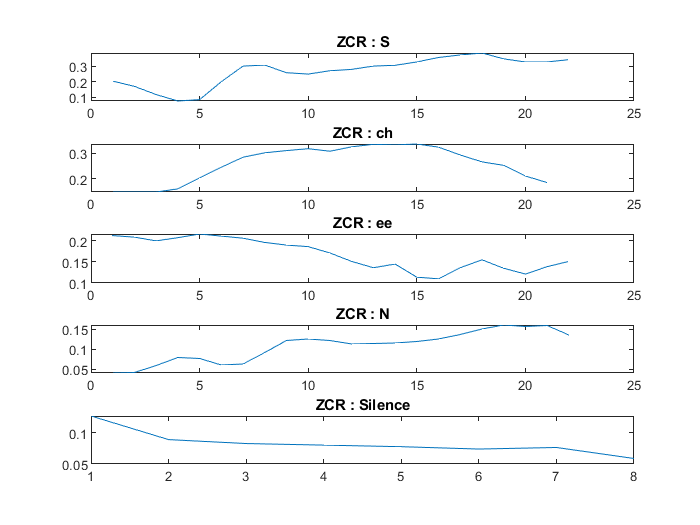

figure();
subplot(5,1,1);
plot(ZCR1);
title('ZCR : S');
subplot(5,1,2);
plot(ZCR2);
title('ZCR : ch');
subplot(5,1,3);
plot(ZCR3);
title('ZCR : ee');
subplot(5,1,4);
plot(ZCR4);
title('ZCR : N');
subplot(5,1,5);
plot(ZCR5);
title('ZCR : Silence');

**Comments and observations:**

**ZCR is relatively low for voiced sounds like "ee" and "n".**

**ZCR is a bit higher for unvoiced as the frequency changes very rapidly in them, in "s" and "ch"**

**ZCR is negligible for silence.**

D. Plot the magnitude spectrum (with magnitude in log scale)  of the 4 speech sounds. Comment/explain how the visual inspection of the spectrum can be used to classify the sound as voiced or unvoiced.

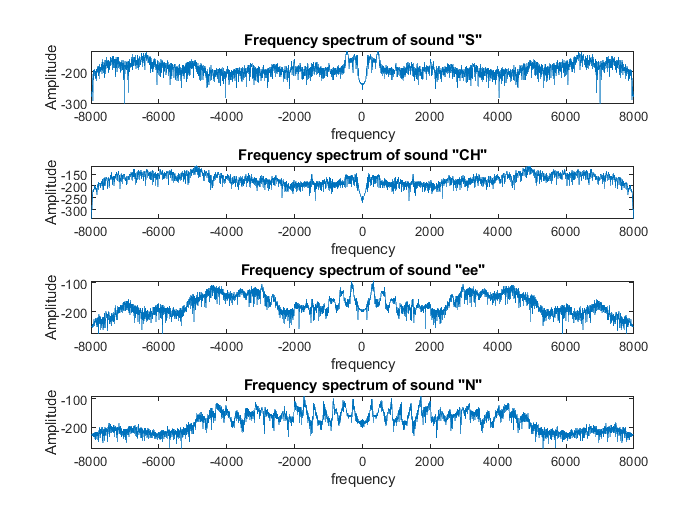

% "S" Sound
dF1= fs/length(t1); 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(4,1,1);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "S"');
% "ch" Sound
dF1= fs/length(t2); 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x2)); % Fourier transform
subplot(4,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "CH"');
% "ee" Sound
dF1= fs/length(t3); 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x3)); % Fourier transform
subplot(4,1,3);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ee"');
% "N" Sound
dF1= fs/length(t4); 
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x4)); % Fourier transform
subplot(4,1,4);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "N"');

**Comments and observations:**

As it can be observed in the spectrum, of "ee" and "N", the frequency components have harmonic structure. Thus, they are classified as voiced.

While the in the frequency spectrum of "S" and "CH", there is no harmonic structure. Thus, they are classified as unvoiced sounds.

Functions Used:

function [y] = quan(data,nobits)
max_data = max(abs(data));
data = data./max_data;
l = length(data);
for i = 1:l
    if nobits>1
     step_size = 2/(2^nobits);
    for j = -1:step_size:1
        if data(i)>=j
            if data(i)<(j+step_size)
                y(i) = j;
            end
        end
    end
    else
        if data(i)>=0
            y(i) = 1;
        else
            y(i)= -1;
        end
    end
end
end

autocorr

function [a]= autocr(y)
sum=0;
for i=0:(length(y)-1)
    sum=0;
    for u=1:(length(y)-i)
        s=y(u)*y(u+i);
        sum=sum+s;
    end
    autocor(i+1)=sum;
end
a=autocor;
return;
end

STE

function[e]=short_term_energy(speechsignal,fs,Frame_size,Frame_shift)
y=speechsignal;
Frame_size= Frame_size/1000;
Frame_shift= Frame_shift/1000 ;
window_length=Frame_size*fs;
sample_shift=Frame_shift*fs;
sum=0 ;energy=0 ;
w=rectwin(window_length);
jj=1 ;

for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
    for j=(((i-1)*sample_shift)+1):(((i-1)*sample_shift)+window_length)
        y(j)=y(j)*w(jj) ;
        jj=jj+1 ;
        yy=y(j)*y(j);
        sum=sum+yy;
    end
    energy(i)=sum ;
    sum=0 ; jj=1 ;
end
w=0;
e=energy;
return ;
end

function[z]=zero_crossing_rate(speechsignal,fs,Frame_size,Frame_shift)
y=speechsignal;
Frame_size= Frame_size/1000;
Frame_shift= Frame_shift/1000 ;
window_length=Frame_size*fs;
sample_shift=Frame_shift*fs;
sum=0 ;energy=0 ;
w=rectwin(window_length);
jj=1 ;

for i=1:(floor((length(y))/sample_shift)-ceil(window_length/sample_shift))
    y(((i-1)*sample_shift)+1)=y(((i-1)*sample_shift)+1)*w(jj);
    jj=jj+1 ;
    for j=(((i-1)*sample_shift)+2):(((i-1)*sample_shift)+window_length)
        y(j)=y(j)*w(jj) ; jj=jj+1 ;
        yy=y(j)*y(j-1);
        if(yy<0)
            sum=sum+1;
        end
    end
    zcr(i)=sum/(2*window_length);
    sum=0 ; jj=1 ;
end
w=0;
z=zcr;
return ;
end